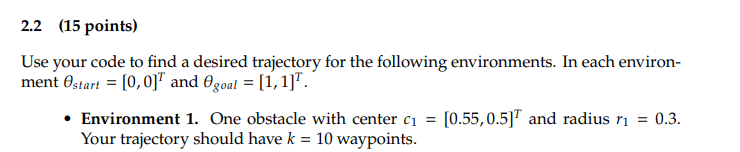

clear
clc
close all

% Start and Goal orientations
theta_start = [0;0];
theta_goal = [1;1];

% Initial trajectory variables

n = 2; % No. of joints / 2-D trajectory. 
k = 10; % No. of waypoints

% Obstacle 1 Paramters
r1 = 0.3;
center1 = [0.55;0.5];

xi_0 = zeros(n, k);
xi_0_vec = reshape(xi_0, [],1);

% Equality constraints for start and goal positions
A = [eye(n), zeros(n,n*(k-1)) ;...
    zeros(n,n*(k-1)), eye(n) ];

B = [theta_start;theta_goal];

% Nonlinear optimization
options = optimoptions('fmincon','Display','iter',...   
    'Algorithm','sqp','MaxFunctionEvaluations',1e4);
xi_star_vec = fmincon(@(xi) cost(xi), xi_0_vec, ...
    [], [], A, B, [], [], [], options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          21    0.000000e+00     1.000e+00     1.000e+00     0.000e+00     2.980e-08  
    1          46    1.152960e-01     7.599e-01     2.401e-01     3.396e-01     4.802e-01  
    2          74    1.288167e-01     6.973e-01     8.235e-02     1.177e-01     3.858e-01  
    3         107    1.301925e-01     6.877e-01     1.384e-02     2.070e-02     3.824e-01  
    4         144    1.304400e-01     6.854e-01     3.323e-03     5.499e-03     9.620e-01  
    5         167    7.032032e+01     3.495e-01     4.900e-01     8.867e-01     1.115e+03  
    6         189    6.352294e+01     1.049e-01     7.000e-01     9.000e-01     1.427e+03  
    7         227    4.385346e+01     1.046e-01     2.326e-03     4.696e+00     1.425e+01  
    8         251    2.747094e+01     6.873e-02     3.430e-01     4.806e+00     8.

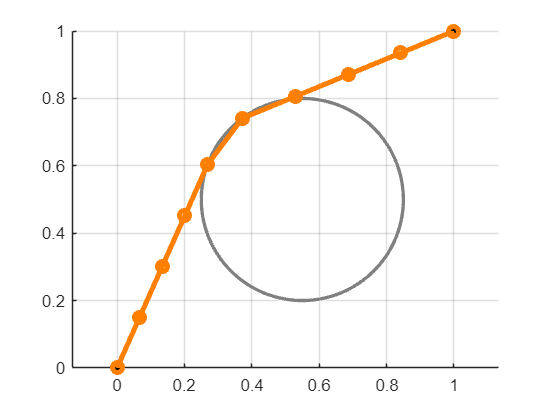


xi_star = reshape(xi_star_vec,2,[]); % to implement

figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal
viscircles(center1', r1, 'Color', [0.5, 0.5, 0.5]);
plot(0, 0, 'ko', 'MarkerFaceColor', 'k')
plot(1, 1, 'ko', 'MarkerFaceColor', 'k')

% Plot Result
grid on
hold on
axis equal
plot(theta_start(1), theta_start(2), 'ko', 'MarkerFaceColor', 'k')
plot(theta_goal(1), theta_goal(2), 'ko', 'MarkerFaceColor', 'k')
% Plot Result
plot(xi_0(1,:), xi_0(2,:), 'o-', 'Color', [0.3, 0.3, ...
 0.3], 'LineWidth', 3);
plot(xi_star(1,:), xi_star(2,:), 'o-',...
    'Color', [1, 0.5, 0], 'LineWidth', 3);


% Cost function to minimize

function C = cost(xi)
        
    gamma = 20;
    xi = reshape(xi,2,[]);
    C = 0;
    r1 = 0.3;
    center1 = [0.55;0.5];
    
    for idx = 2:length(xi)
        Urep1 = 0;

        if (norm(center1 - xi(:,idx)) <=r1) 
            Urep1 = 0.5*gamma*((1/(norm(center1-xi(:,idx)))) - (1/r1))^2;
        end

        C = Urep1  + C + norm(xi(:,idx) - xi(:,idx-1))^2;
    end
end